# ROS|MATLAB Images & Point Cloud & Transformations

### Overview

This notebook goes through:

    RGB Images

- Acessing the raw RGB data from the camera (aka. "taking a picture" of what the robot is seeing)

    Point Clouds

- Acessing the raw depth data from the camera ("taking a point cloud")

- Extracting the transformation between robot frames

- Applying a frame transformation to the collected point cloud using `pctransform`

### Acessing Raw RGB Data using ROS

Create a ros subscriber to the `/camera/rgb/image_raw` topic. This is the topic that is used to acess image data from the camera on the robot.

rgb_sub = rossubscriber('/camera/rgb/image_raw','DataFormat','struct')

"Grab" the data that is on the topic at this moment. 

You would want the robot arm to already be in the position where you want to "take a picture" or see what the robot is seeing.

rosImg = receive(rgb_sub)

Read the image data into the varaible `myImg`. 

myImg = rosReadImage(rosImg,"PreserveStructureOnRead",true);

`myImg` should be of size M x N x 3 where M is the number rows of pixels, N is the number of columns of pixels, and 3 is the 1x3 RGB vector for each pixel.

See the image displayed

figure, imshow(myImg);

### Acessing Raw Depth Data Using ROS

Create a ros subscriber to the `/camera/depth/points` topic. 

This is the topic that is used to acess depth data from the camera sensor on the robot.

pt_cloud_sub = rossubscriber('/camera/depth/points','DataFormat','struct');

"Grab" the *'sensor_msgs/PointCloud2'* that is on the topic at this moment. 

Note: You would want the robot arm to already be in the position where you want to "take a point cloud" or see what the robot is seeing.

pc = receive(pt_cloud_sub,2);

#### Visualize the ROS point cloud data

The ROS point cloud message can be visualized via the [rosPlot](https://www.mathworks.com/help/releases/R2025a/ros/ref/rosplot.html?searchPort=41031)() method as seen below. 

Note how color and depth are integrated together, though the z-axis is inverted as we are measuring depth from the top (taller things are closer, shorter things are further away).

rosPlot(pc);

#### Convert from ROS to matlab formats

We can convert the ROS message to a Matlab RGB matrix that shares the same structure as the image (480,640,3) via the  [rosReadXYZ](https://www.mathworks.com/help/releases/R2025a/ros/ref/rosreadxyz.html?searchPort=41031)() method.

The option '

xyz = rosReadXYZ(pc,"PreserveStructureOnRead",true);

Matlab [`pointCloud`](https://www.mathworks.com/help/releases/R2025a/vision/ref/pointcloud.html?overload=vision%2FpointCloud+false&searchPort=41031)`()`method returns a [`pointCloud`](https://www.mathworks.com/help/releases/R2025a/vision/ref/pointcloud.html?overload=vision%2FpointCloud+false&searchPort=41031) object that consists of xyz coordinates, limits, and possibly color.

Below we convert the structured xyz data into a [`pointCloud`](https://www.mathworks.com/help/releases/R2025a/vision/ref/pointcloud.html?overload=vision%2FpointCloud+false&searchPort=41031) object which really captures depth and coordinates.

ptCloud = pointCloud(xyz); % make xyz a pointCloud object

The [`pointCloud`](https://www.mathworks.com/help/releases/R2025a/vision/ref/pointcloud.html?overload=vision%2FpointCloud+false&searchPort=41031) can be visualized using [pcshow](https://www.mathworks.com/help/releases/R2025a/vision/ref/pcshow.html?searchPort=41031)(). By invoking the vertical axis direction (by default the z-axis) down, we can see the points more intuitively from the bottom-up (try suppressing the option).

pcshow(ptCloud, 'VerticalAxisDir','Down')
xlabel('x-axis'); ylabel('y-axis');zlabel('z-axis');

**Take note**: 

`ptCloud` is currently with respect to the `camera_depth_link` instead of the r**obot **`base_link` or the `world`.

### Transforming point cloud data to another frame

When the depth camera captures point clouds, each of those points coordinates is with respect to the camera_link frame (the lens of the camera). We want to transform the data so that it is with respect to the base. 

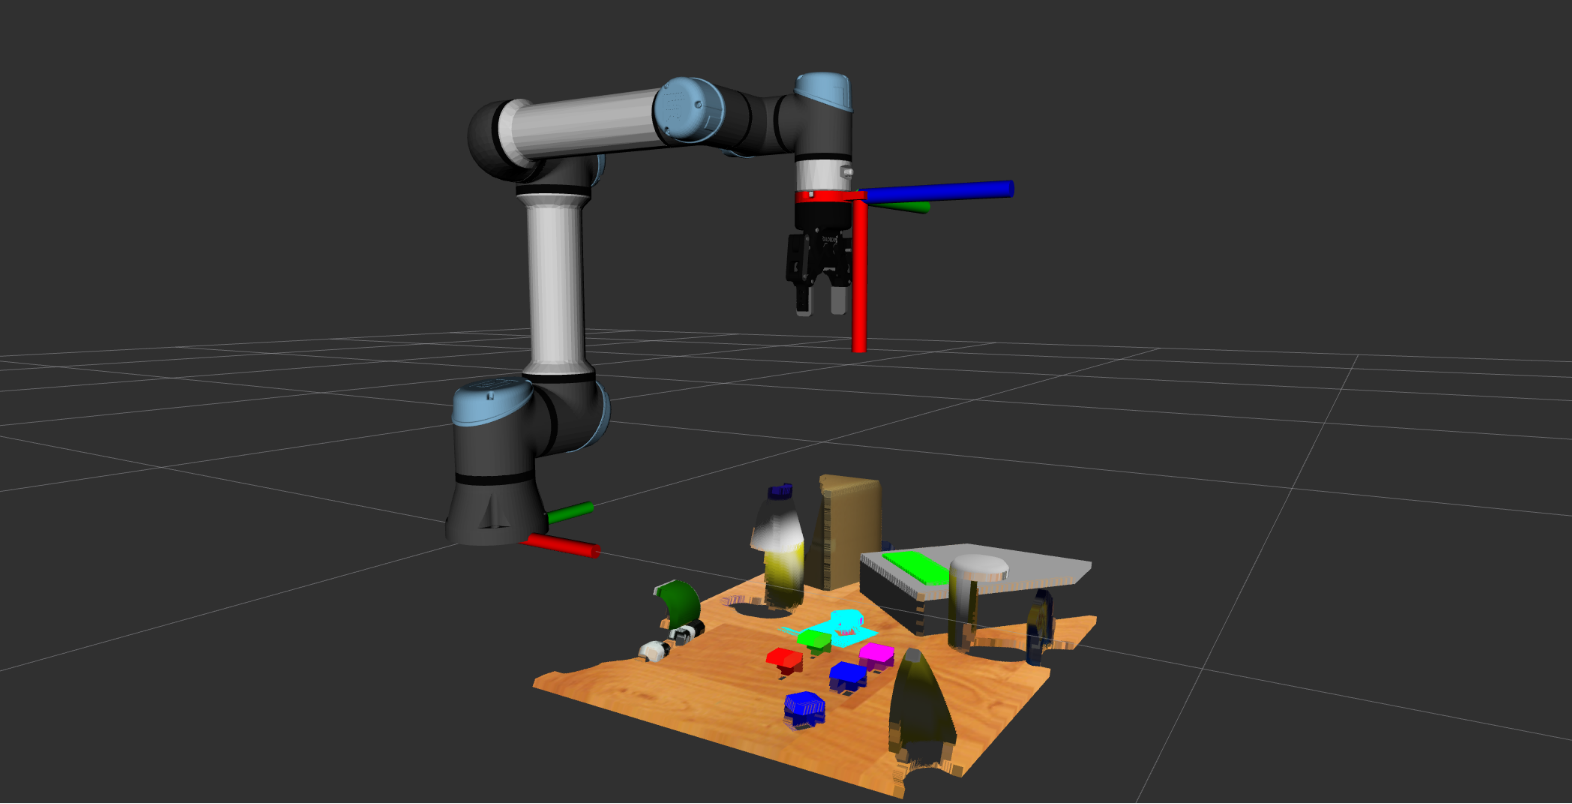 

Once we have the transformation, we will need to appply to each and every point by using pctransform. Below a visualization from RVIZ of all the points that need to be transformed:

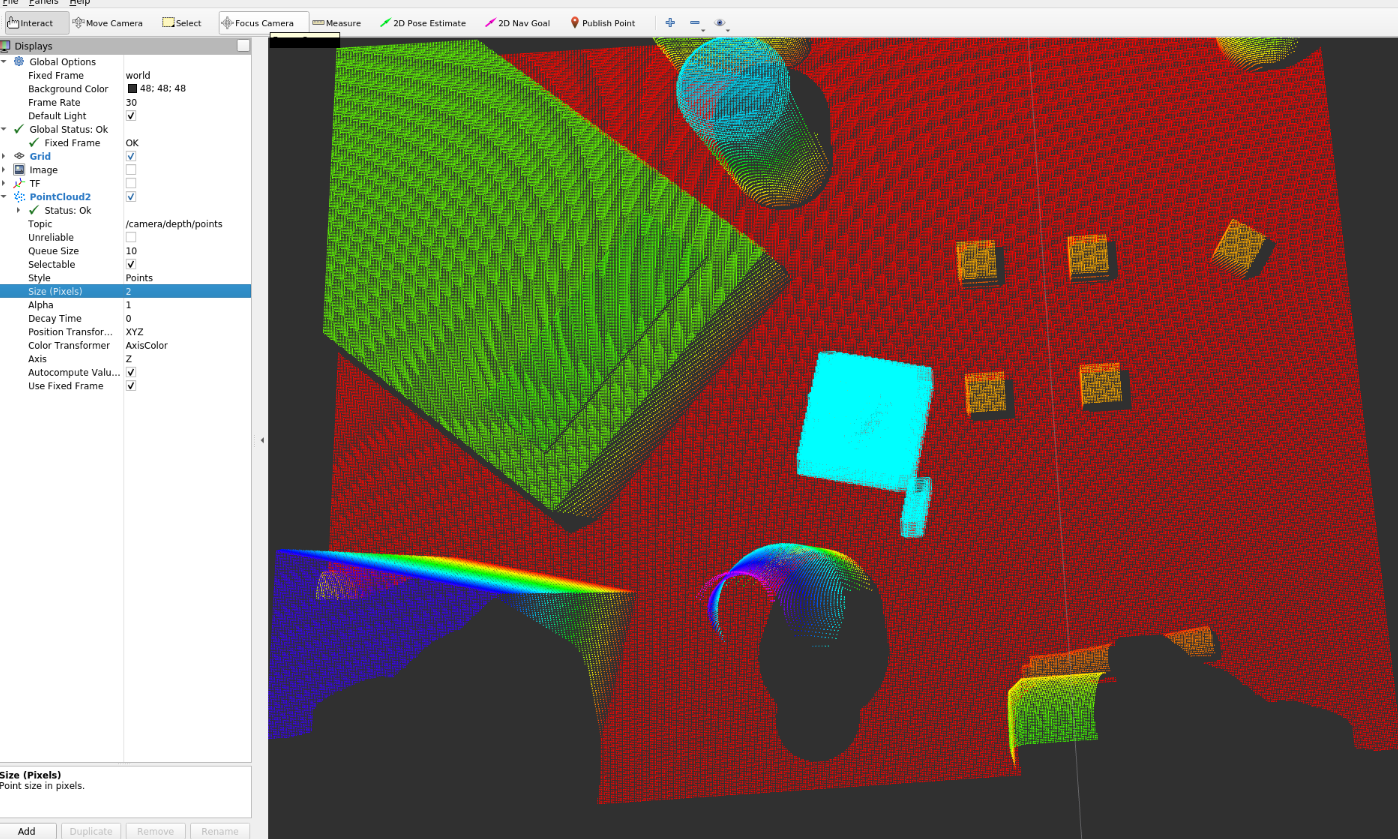

#### Getting the base_link to camera_link via ROS

Create `tftree` variable

tftree = rostf('DataFormat','struct');    

Specify the target frame base_link:

base_frame = 'base_link';

Specify the current frame:

cam_frame = pc.Header.FrameId; %'camera_depth_link';

Compute the ROS/Gazebo transform from base_link to camera_depth_link of the robot arm in the current position via TF:

waitForTransform(tftree, base_frame, cam_frame);
base_to_camera = getTransform(tftree, base_frame, cam_frame, rostime('now'),'Timeout', 5);

#### base_to_camera 4x4 matrix

Make a `pos` variable from the translation

pos = [ base_to_camera.Transform.Translation.X, ... 
        base_to_camera.Transform.Translation.Y, ...
        base_to_camera.Transform.Translation.Z]; 

Use `base_to_camera` rotation and format into `q`

q = UnitQuaternion(base_to_camera.Transform.Rotation.W, ...
                   [base_to_camera.Transform.Rotation.X, ...

base_to_cam_pose =    -0.0002   -1.0000    0.0008    0.5469
   -1.0000    0.0002    0.0009    0.1332
   -0.0009   -0.0008   -1.0000    0.4879
         0         0         0    1.0000


                    base_to_camera.Transform.Rotation.Y, ...
                    base_to_camera.Transform.Rotation.Z]);

Compute the 4x4 pose for base to camera

q.T;
base_to_cam_pose = transl(pos) * q.T   % now a 4x4

#### Applying the Transformation to the Point Cloud

Transform the point cloud to `base_link with `[`pctransform`](https://www.mathworks.com/help/releases/R2025a/vision/ref/pctransform.html?searchPort=41031)`:`

tform = rigidtform3d(base_to_cam_pose); % make the transformation of type rigidtform3d so pctransform can use it
ptCloud_tform = pctransform(ptCloud,tform);

#### Visualizing the New Point Cloud

Let us re-plot the pointCloud object once again and compare coordinates:

figure, pcshow(ptCloud_tform);
xlabel('x-axis'); ylabel('y-axis');zlabel('z-axis');

Choose a particular point in the point-cloud, like the tip of the bottle. 

Notice how wrt camera_link frame, the coordinates are: (0, -0.2, 0.45).

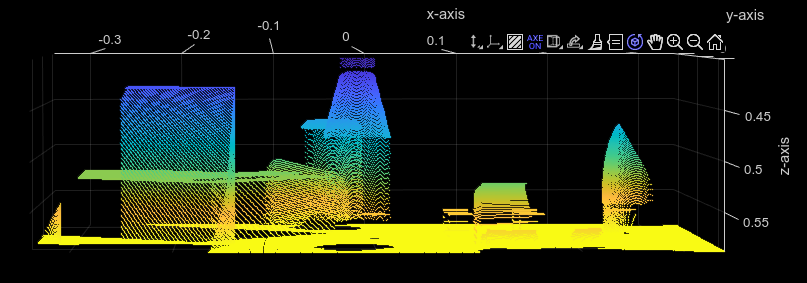

But, wrt to the base_link frame, the coordinates are: (0.4, 0.2, 0.075).